# Example 13.2 - Torque-free motion of a spacecraft

A rigid spacecraft with principal moments of inertia $J_{xx}$= 4000 $kg.m^2$, $J_{yy}$ = 7500 $kg.m^2$, $J_{zz}$ = 8500 $kg.m^2$ has an initial angular velocity $\omega(0)$=(0.1, -0.2, 0.5) rad/s and an initial attitude $\psi(0)=0$, $\theta(0)=\frac{\pi}{2}$, $\phi(0)=0$. Simulate the subsequent rotation of the spacecraft

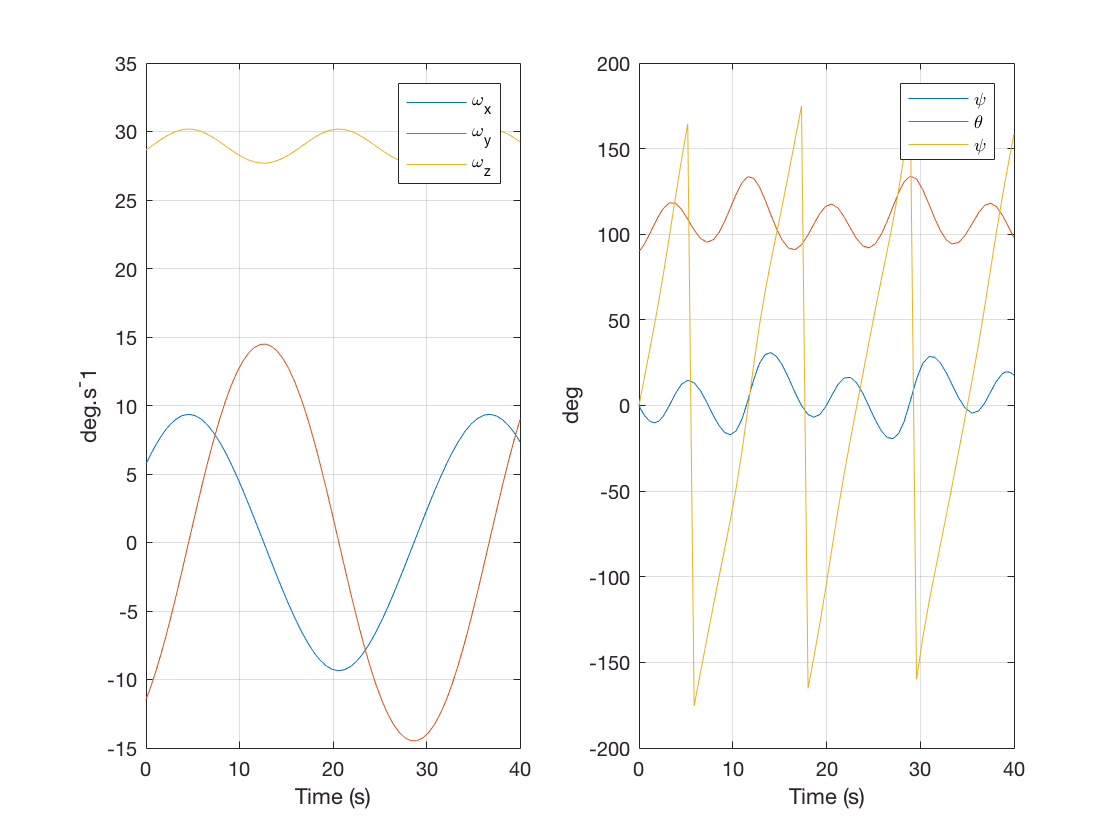


psi0 = 0;theta0 = 0.5*pi;phi0 = 0;
qtemp = angle2quat(psi0,theta0,phi0 ,'ZXZ')'; % 3-1-3 euler sequence
q0 = [qtemp(2:4);qtemp(1)];
w0 = [0.1 -0.2 0.5]';

[t,x]=ode45(@(t,y) eomRotation(t,y,massModel,forceModel),[0 40],[w0;q0]);
w = x(:,1:3); q = [x(:,7) x(:,4:6)];
[yaw,pitch,roll] = quat2angle(q,'ZXZ');
subplot(121),plot(t,w*180/pi),grid on;
xlabel('Time (s)');ylabel('deg.s^-1');legend('\omega_x','\omega_y','\omega_z');
subplot(122),plot(t,[yaw pitch roll]*180/pi),grid on;
xlabel('Time (s)');ylabel('deg');legend('\psi','\theta','\psi');

The precession is evident in the oscillation of $\omega_x$, $\omega_y$ and $\psi$, $\phi$, but the nutation is observed in the oscillation of $\omega_z$ and $\theta$. **Note **This result would not be seeing in a linear approximation of the equations of motion. Here the nonlinear simulation shows actual response. 

Input Properties

function J = massModel
    J = eye(3);
    J(1,1)=4000;  %kg-m^2
    J(2,2)=7500;  %kg-m^2 
    J(3,3)=8500;  %kg-m^2 
end

function M = forceModel
    M = zeros(3,1);
end